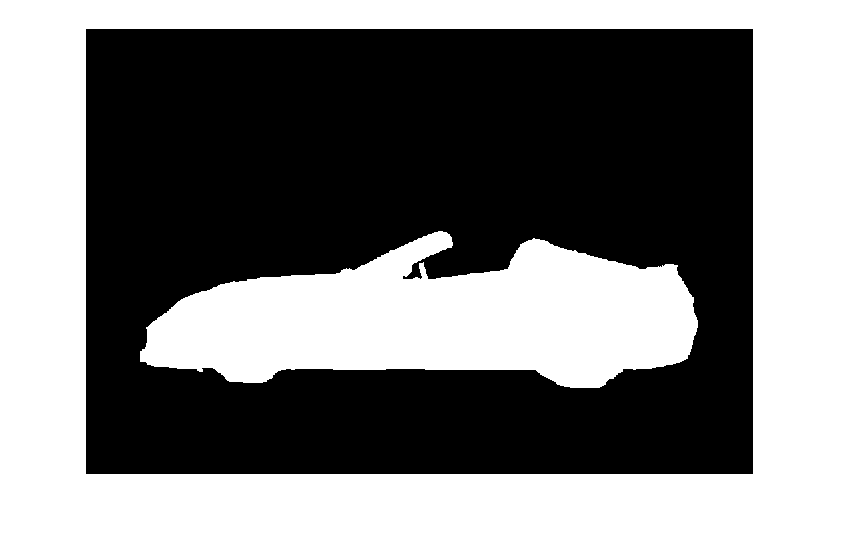

img = imread('car.bmp');
img = im2double(img);
mask = imread('mask.bmp');
carmask = (mask == 0);
bgmask = (mask ~= 0);
imshow(carmask);

len = 100;
[height, width] = size(img);

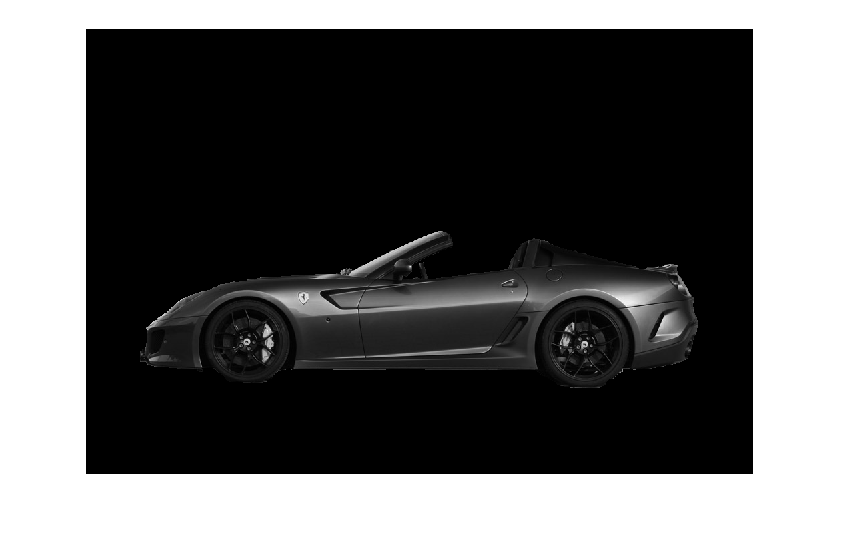

car = zeros(size(img));
car(carmask) = img(carmask);
imshow(car);

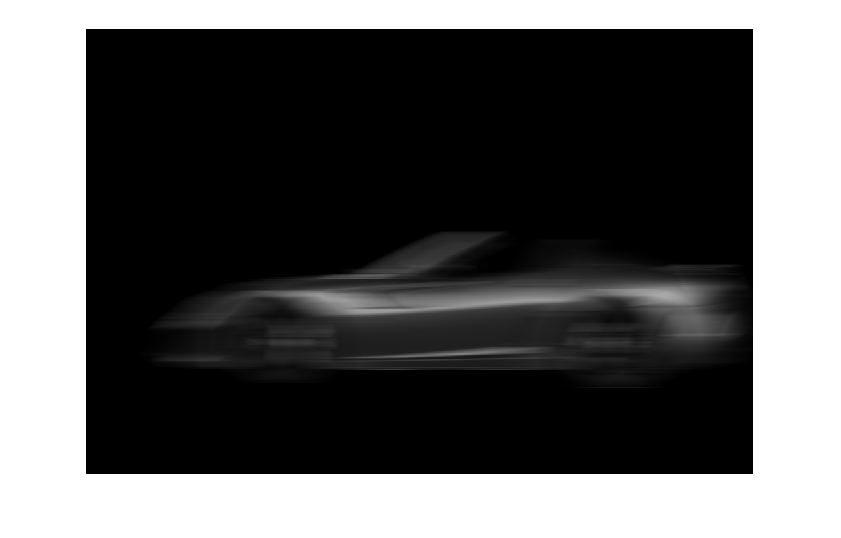


carh = 2 * fspecial('motion',len * 2,0);
carh(len+2:end) = 0;

carblur = imfilter(car,carh,'replicate');
imshow(carblur);

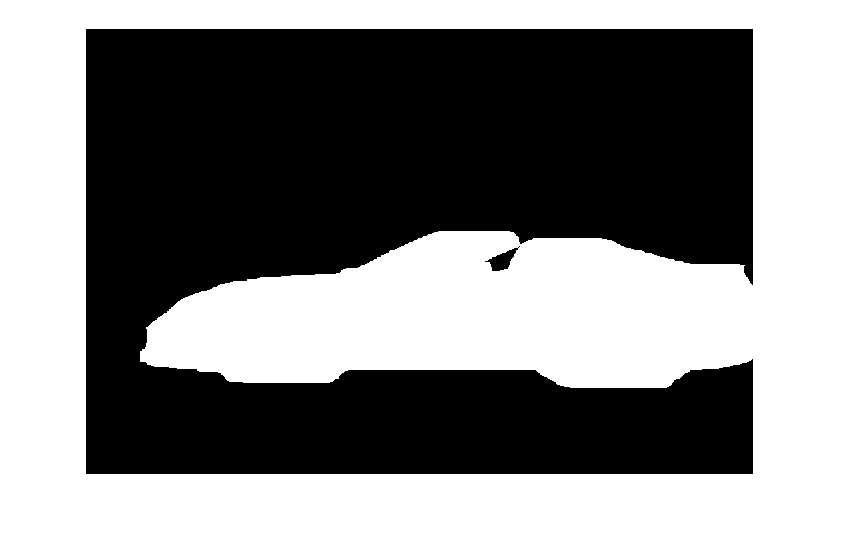

carblurmask = (carblur > 0);
imshow(carblurmask);

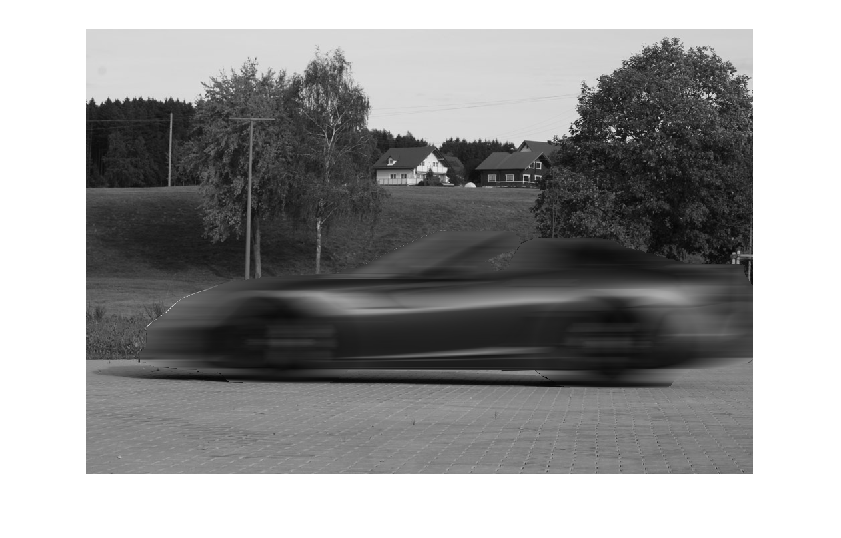

carmotion = img;
carblur = imfilter(img, carh, 'replicate');
carmotion(carblurmask) = carblur(carblurmask);
imshow(carmotion);

%carmotion(carmask) = img(carmask) * 0.5 + carmotion(carmask) * 0.5;
imshow(carmotion);

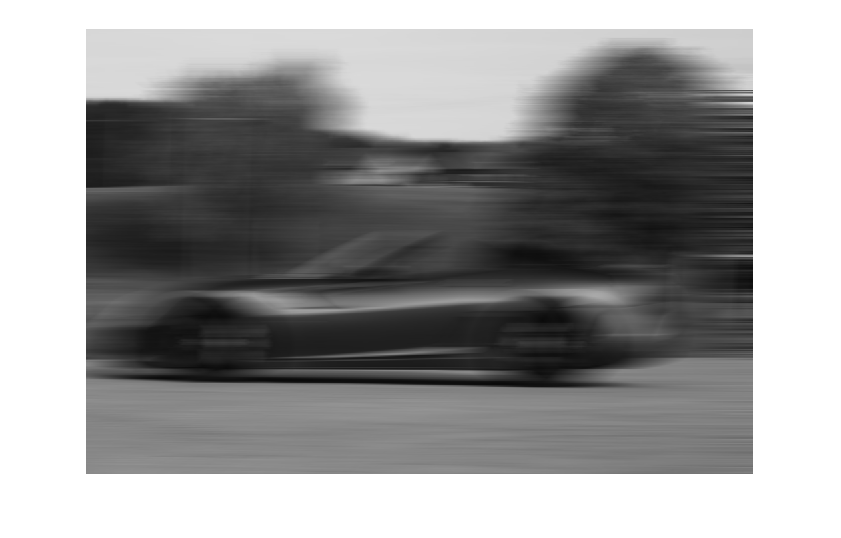

bgh = 2 * fspecial('motion',len * 2,0);
bgh(1: len) = 0;

bgmotion = imfilter(img,bgh,'replicate');
imshow(bgmotion);

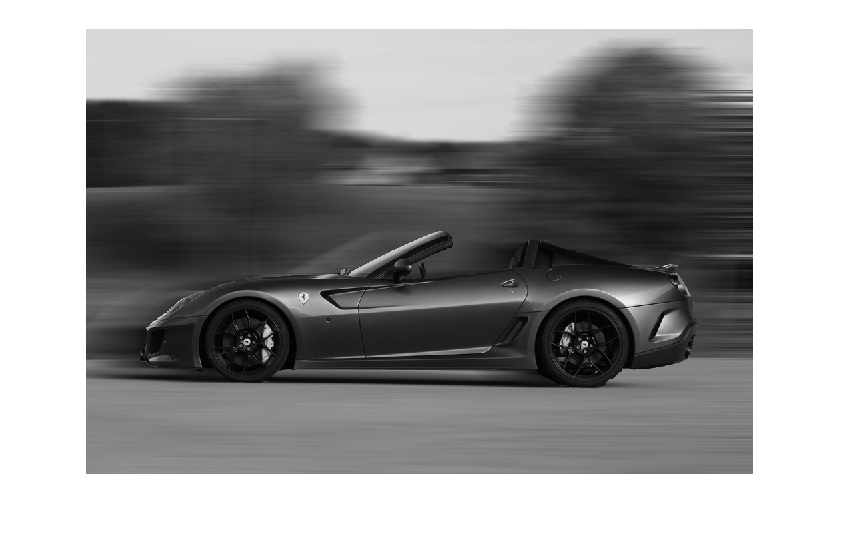

bgmotion(carmask) = img(carmask);
imshow(bgmotion);

%h = fspecial('motion',len * 2,0);
h = carh;
%temp = imfilter(img, h, 'circular');
temp = carmotion;
imshow(temp);

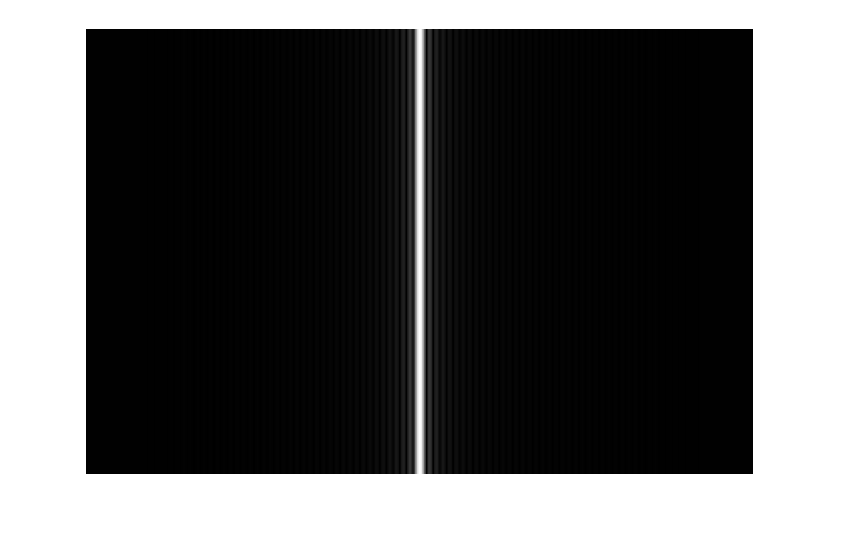

n = 0.00002;
carH = fft2(h, height, width);
imshow(abs(fftshift(carH)));

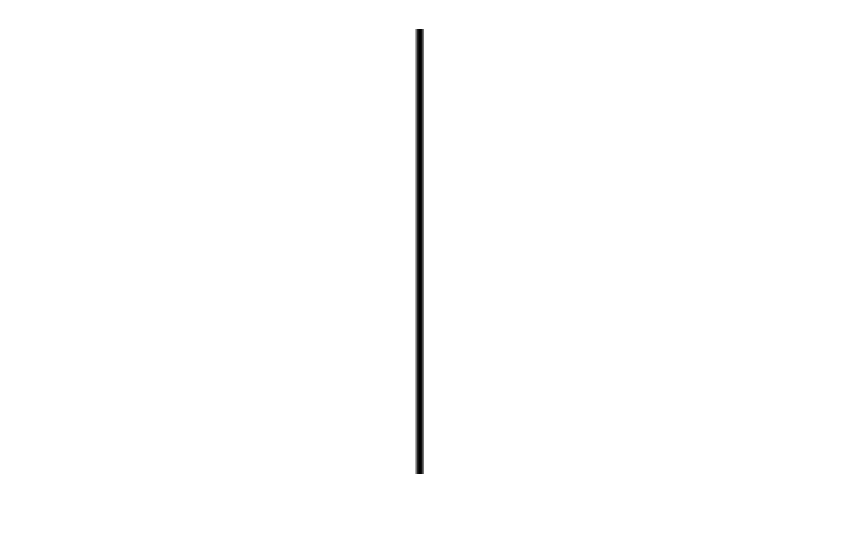


carH(abs(carH) < n) = n;
carR = ones(height, width)./carH;
imshow(log(abs(fftshift(carR))));

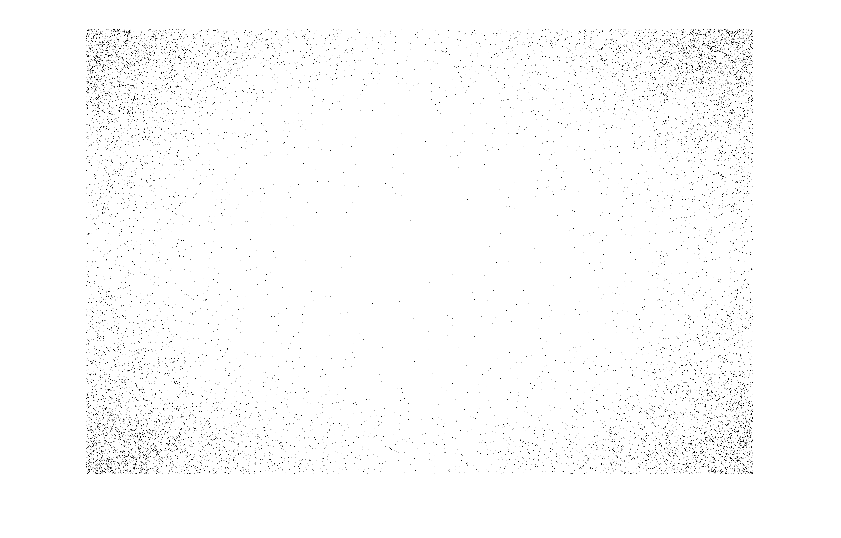


carmotionF = fft2(temp, height, width);
imshow(log(abs(fftshift(carmotionF))));

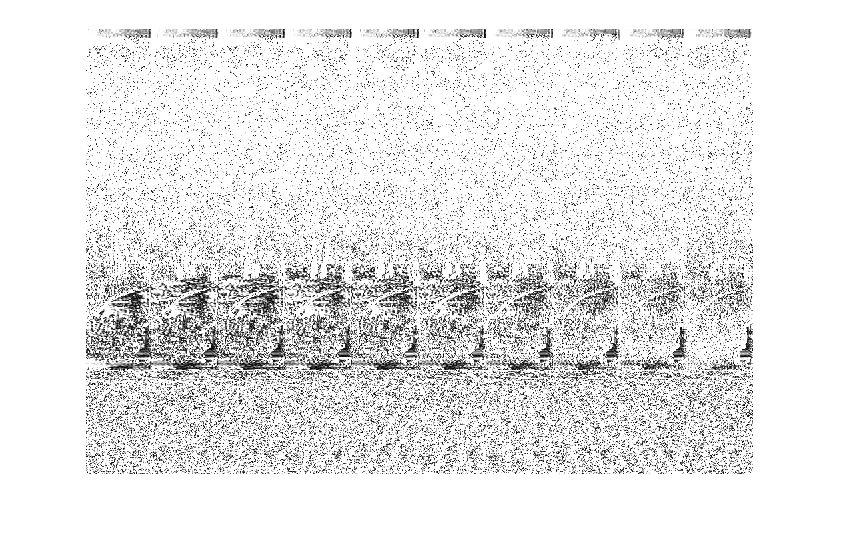


carmotionF2 = carmotionF .* carR;
carf2 = abs(ifft2(carmotionF2));
imshow(carf2);